clear
clc
close all
load gaitdata.mat;
%keep only sagittal hip data
TBL = removevars(gaitdata,{'aKsag', 'aAsag', 'mKsag_abs', 'mKsag_max', 'mKsag_min', 'mKsag_rel', 'mKsag_rms', 'pKsag_abs', 'pKsag_max', 'pKsag_min', 'pKsag_rel', 'mAsag_abs', 'mAsag_max', 'mAsag_min', 'mAsag_rel', 'mAsag_rms', 'pAsag_abs', 'pAsag_max', 'pAsag_min', 'pAsag_rel'});
% Join tables
id=31

id = 31

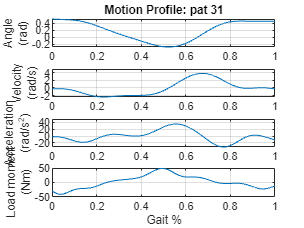

stridetime = 1;
gaitprofile_inst=gaitprofile(['pat ' char(string(id))],TBL(id,:),stridetime,1,[],true);
gaitprofile_inst.plot;

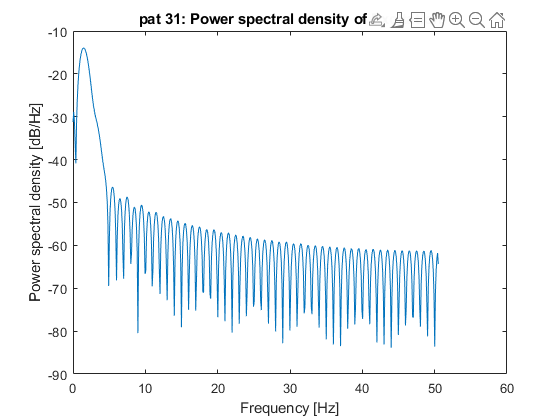

figure
gaitprofile_inst.showSpectrum

load actuatordata.mat
mot_id = 6

mot_id = 6

motor_inst = motor(actuatordata(mot_id,:),1.38,2.06,[]);

geareval_inst = geareval(motor_inst, gaitprofile_inst,1,1, 'sea',true)

geareval_inst =   geareval with properties:

                 mot: [1×1 motor]
             profile: [1×1 gaitprofile]
          efficiency: 1
        assistfactor: 1
               issea: 1
             results: []
                 fig: []
    NKfigMrmsContour: []
    NKfigPmaxContour: []
    NKfigPavgContour: []
                 zci: @(v)find(v(:).*circshift(v(:),[-1,0])<=0)


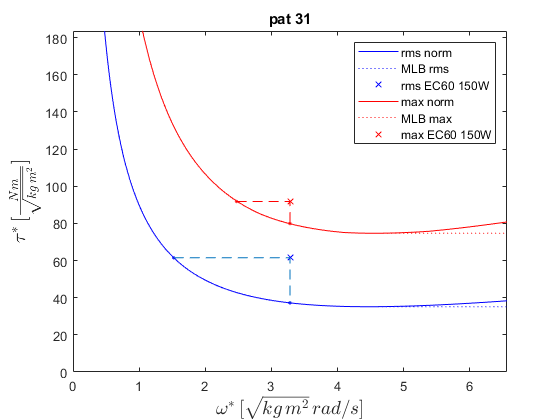

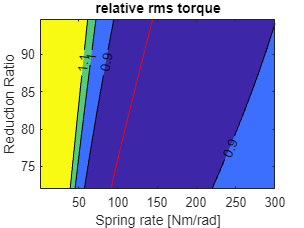

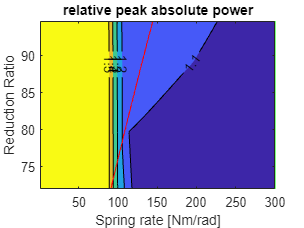

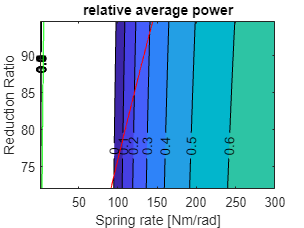

geareval_inst.eval(200, 500,'Krange',[1,300], 'nNK',[150, 500])

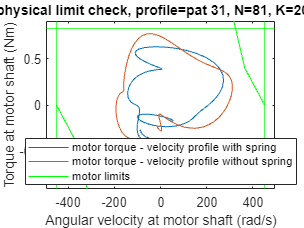

margs = struct with fields:
         speed_margin: 0.2517
    moment_margin_rms: 0.4284
    moment_margin_max: 0.2378


margfig =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


[margs, margfig] = geareval_inst.margins(81,'K',200)

% [margs, margfig] = geareval_inst.margins(81) % only evaluate stiff
% actuator

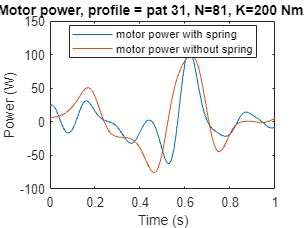

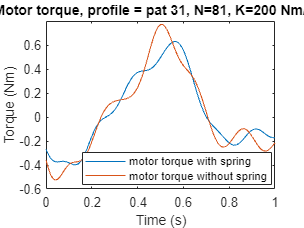

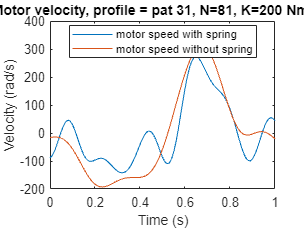

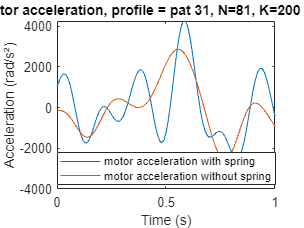

results_sel = struct with fields:
          mnospring: [101×1 double]
      omeganospring: [101×1 double]
      accelnospring: [101×1 double]
          pnospring: [101×1 double]
            mspring: [101×1 double]
        omegaspring: [101×1 double]
        accelspring: [101×1 double]
            pspring: [101×1 double]
      mnospring_rms: 0.3591
        mspring_rms: 0.3163
    mspring_rms_rel: 0.8809
      pnospring_max: 99.1316
        pspring_max: 106.0511
    pspring_max_rel: 1.0698
      pnospring_avg: 4.4083
        pspring_avg: 2.2700
    pspring_avg_rel: 0.5149
          enospring: 4.4083
            espring: 2.2700
        espring_rel: 0.5149


figsselected =   1×4 Figure array:

    Figure    Figure    Figure    Figure


[results_sel, figsselected]=geareval_inst.plotSelected('N', 81, 'K', 200)